# Using DALL·E™ to generate images

This example shows how to generate images using the `openAIImages` object.

To run this example, you need a valid OpenAI™ API key. Creating images using DALL-E may incur a fee.

loadenv(".env")
addpath('..')

## Image Generation with DALL·E 3

Create an `openAIImages` object with `ModelName` `dall-e-3`.

mdl = openAIImages(ModelName="dall-e-3");

Generate and visualize an image. This model only supports the generation of one image per request.

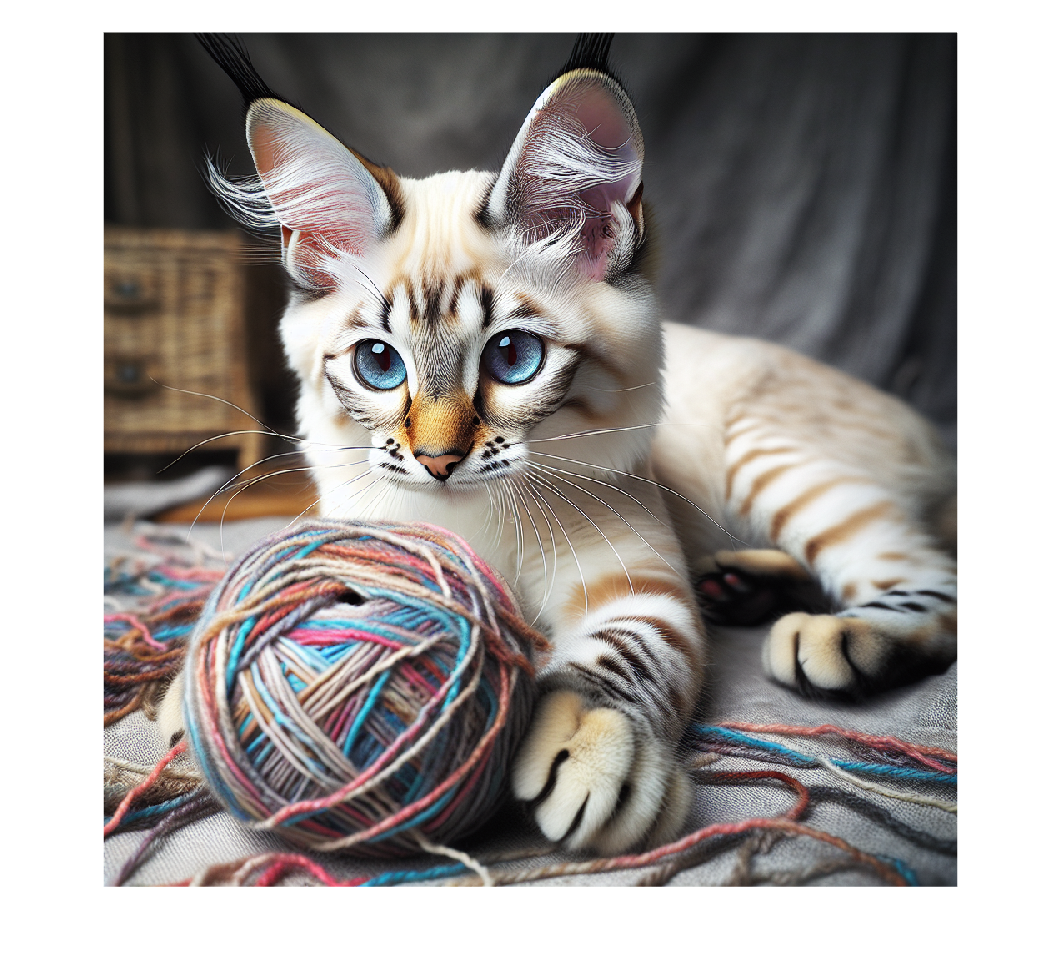

images = generate(mdl,"A Lynx Point Siamese cat playing with some yarn");
figure
imshow(images{1})

You can also define the style and quality of the image

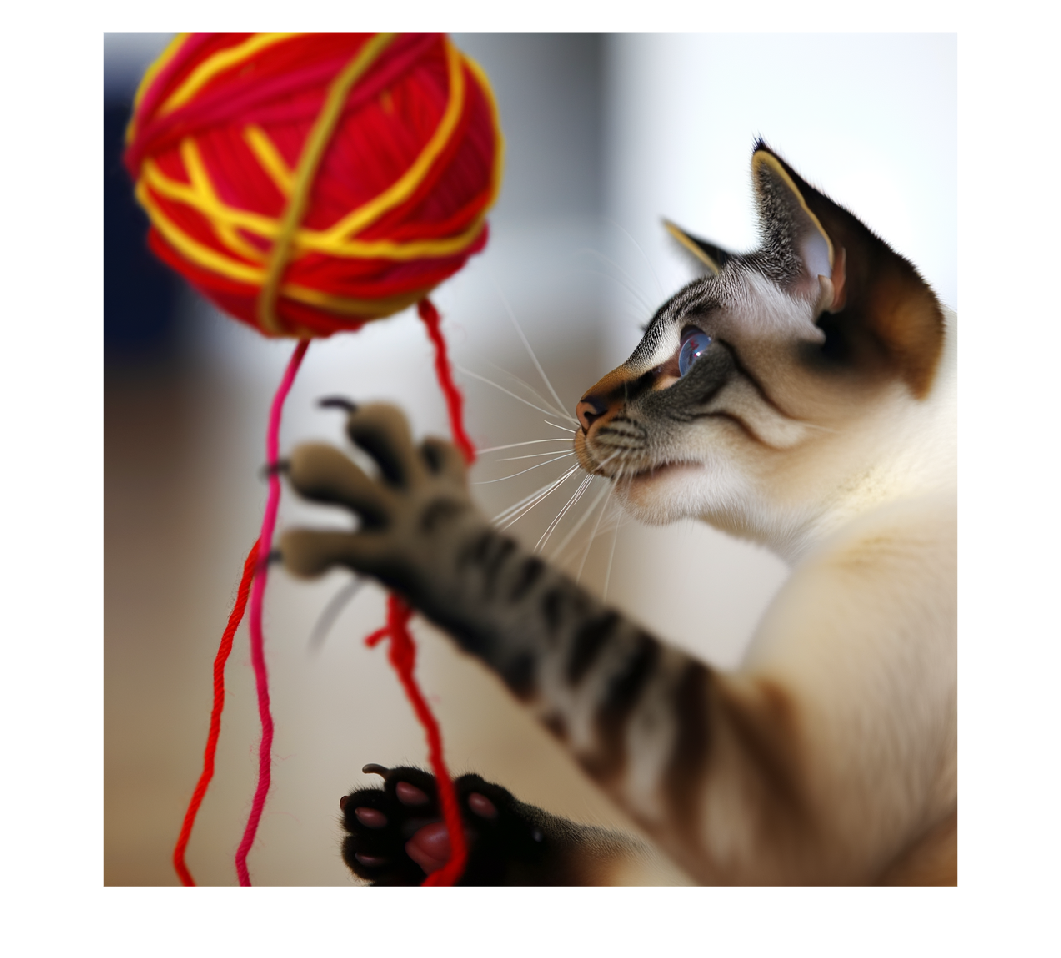

images = generate(mdl,"A Lynx Point Siamese cat playing with some yarn", Quality="hd", Style="natural");
figure
imshow(images{1})

*Copyright 2024 The MathWorks, Inc.*